% This script is based on model_comp_fitting_v2.m and plots the winner
% counts of how often each model fit the best in a single session.
subjID = 8;
%% model parameters outside the loop
% define PMF
P_Afirst                      = @(SOA, mu, sig, c, lambda) lambda/3 + (1-lambda).*normcdf(-c, SOA - mu, sig);
P_Vfirst                      = @(SOA, mu, sig, c, lambda) lambda/3 + (1-lambda).*(1 - normcdf(c, SOA-mu, sig));
P_simultaneous                = @(SOA, mu, sig, c, lambda) ...
    1 - (lambda/3 + (1-lambda).*normcdf(-c, SOA - mu, sig)) ...
    - (lambda/3 + (1-lambda).*(1 - normcdf(c, SOA-mu, sig)));

n_rep = 100; % how many repetitions to fit 5 models
numM                          = 5; %number of models
n_init                        = 10; % how many initialization for each model
numP                          = [8,7,7,6,5]; %number of free parameters for M1, M2, M3, M4, M5 respectively

%define upper and lower bounds
lb                            = {[-150, -150, 10, 10, 50, 50, 0.01, 0.01], ...%M1
    [-150, -150, 10, 1, 1, 0.01, 0.01] ...%M2
    [-150, -150, 10, 10, 1, 0.01, 0.01], ...%M3
    [-150, -150, 10, 1, 0.01, 0.01], ...%M4
    [-150, 10, 1, 0.01, 0.01]};%M5
ub                            = {[150, 150, 350, 350, 400, 400, 0.06, 0.06], ...%M1
    [150, 150, 350, 400, 400, 0.06, 0.06], ...%M2
    [150, 150, 350, 350, 400, 0.06, 0.06], ...%M3
    [150, 150, 350, 400, 0.06, 0.06], ...%M4
    [150, 350, 400, 0.06, 0.06]};%M5
init_fun                      = @(a,b) rand(1,length(a)).*(b-a) + a;
options                       = optimoptions(@fmincon,'MaxIterations',1e5,'Display','off');
estP                          = cell(9,numM); % 9 sessions x 5 models
[min_NLL, AIC]                = deal(cell(9, numM)); % 9 sessions x 5 models
c_model = zeros(9, numM); % 9 sessions x 5 models; numbers are the counts of best-fitting 

%% organize data inside the loop
for sess                      = 1:9
    
    %%%%% pre-test
    load(['pretest_sub' num2str(subjID) '_session' num2str(sess) '.mat'])
    pre_s_unique                  = ExpInfo.SOA; % unique SOA levels, in s
    pre_ms_unique                 = pre_s_unique * 1e3; % unique SOA levels, in ms
    pre_numTrials                 = ExpInfo.nTrials; % num of trials per SOA
    % inititate
    pre_r_org                     = NaN(length(pre_s_unique), pre_numTrials);
    pre_respCount                 = NaN(3, length(pre_s_unique));
    for i                         = 1:length(pre_s_unique)
        iSOA                          = pre_s_unique(i);
        iResp                         = Response.order(ExpInfo.trialSOA == iSOA);
        pre_r_org(i,:)                = iResp; % this matrix has a size of length(s_unique) x numTrials
        for j                         = unique(Response.order) % 1 = V first, 2 = simultaneous, 3 = A first
            pre_respCount(j,i)            = sum(iResp == j);
        end
    end
    pre_pResp                     = pre_respCount/pre_numTrials;
    pre_nT_A1st                   = pre_respCount(3,:);
    pre_nT_V1st                   = pre_respCount(1,:);
    pre_nT_simul                  = pre_respCount(2,:);

    %%%%% post-test
    % load data and define key parameters
    load(['posttest_sub' num2str(subjID) '_session' num2str(sess) '.mat'])
    post_s_unique                 = ExpInfo.SOA; % unique SOA levels, in ms
    post_ms_unique                = post_s_unique * 1e3; % unique SOA levels, in s
    post_numTrials                = ExpInfo.nTrials; % num of trials per SOA
    % inititate
    post_r_org                    = NaN(length(post_s_unique), post_numTrials);
    post_respCount                = NaN(3, length(post_s_unique));
    for i                         = 1:length(post_s_unique)
        iSOA                          = post_s_unique(i);
        iResp                         = Response.order(ExpInfo.trialSOA == iSOA);
        post_r_org(i,:)               = iResp; % this matrix has a size of length(s_unique) x numTrials
        for j                         = unique(Response.order) % 1 = V first, 2 = simultaneous, 3 = A first
            post_respCount(j,i)           = sum(iResp == j);
        end
    end
    post_pResp                    = post_respCount/post_numTrials;
    post_nT_A1st                  = post_respCount(3,:);
    post_nT_V1st                  = post_respCount(1,:);
    post_nT_simul                 = post_respCount(2,:);

    %% specify models inside the loop
    M1                            = @(p) -pre_nT_A1st*log(P_Afirst(pre_ms_unique, p(1), p(3), p(5), p(7)))'...
        -pre_nT_V1st*log(P_Vfirst(pre_ms_unique, p(1), p(3), p(5), p(7)))'...
        -pre_nT_simul*log(P_simultaneous(pre_ms_unique, p(1), p(3), p(5), p(7)))'...
        -post_nT_A1st*log(P_Afirst(post_ms_unique, p(2), p(4), p(6), p(8)))' ...
        -post_nT_V1st*log(P_Vfirst(post_ms_unique, p(2), p(4), p(6), p(8)))'...
        -post_nT_simul*log(P_simultaneous(post_ms_unique, p(2), p(4), p(6), p(8)))';

    M2                            = @(p) -pre_nT_A1st*log(P_Afirst(pre_ms_unique, p(1), p(3), p(4), p(6)))' ...
        -pre_nT_V1st*log(P_Vfirst(pre_ms_unique, p(1), p(3), p(4), p(6)))'...
        -pre_nT_simul*log(P_simultaneous(pre_ms_unique, p(1), p(3), p(4), p(6)))'...
        -post_nT_A1st*log(P_Afirst(post_ms_unique, p(2), p(3), p(5), p(7)))' ...
        -post_nT_V1st*log(P_Vfirst(post_ms_unique, p(2), p(3), p(5), p(7)))'...
        -post_nT_simul*log(P_simultaneous(post_ms_unique, p(2), p(3), p(5), p(7)))';

    M3                            = @(p) -pre_nT_A1st*log(P_Afirst(pre_ms_unique, p(1), p(3), p(5), p(6)))' ...
        -pre_nT_V1st*log(P_Vfirst(pre_ms_unique, p(1), p(3), p(5), p(6)))'...
        -pre_nT_simul*log(P_simultaneous(pre_ms_unique, p(1), p(3), p(5), p(6)))'...
        -post_nT_A1st*log(P_Afirst(post_ms_unique, p(2), p(4), p(5), p(7)))' ...
        -post_nT_V1st*log(P_Vfirst(post_ms_unique, p(2), p(4), p(5), p(7)))'...
        -post_nT_simul*log(P_simultaneous(post_ms_unique, p(2), p(4), p(5), p(7)))';...

    M4                            = @(p) -pre_nT_A1st*log(P_Afirst(pre_ms_unique, p(1), p(3), p(4), p(5)))' ...
        -pre_nT_V1st*log(P_Vfirst(pre_ms_unique, p(1), p(3), p(4), p(5)))'...
        -pre_nT_simul*log(P_simultaneous(pre_ms_unique, p(1), p(3), p(4), p(5)))'...
        -post_nT_A1st*log(P_Afirst(post_ms_unique, p(2), p(3), p(4), p(6)))' ...
        -post_nT_V1st*log(P_Vfirst(post_ms_unique, p(2), p(3), p(4), p(6)))'...
        -post_nT_simul*log(P_simultaneous(post_ms_unique, p(2), p(3), p(4), p(6)))';

    M5                            = @(p) -pre_nT_A1st*log(P_Afirst(pre_ms_unique, p(1), p(2), p(3), p(4)))' ...
        -pre_nT_V1st*log(P_Vfirst(pre_ms_unique, p(1), p(2), p(3), p(4)))'...
        -pre_nT_simul*log(P_simultaneous(pre_ms_unique, p(1), p(2), p(3), p(4)))'...
        -post_nT_A1st*log(P_Afirst(post_ms_unique, p(1), p(2), p(3), p(5)))' ...
        -post_nT_V1st*log(P_Vfirst(post_ms_unique, p(1), p(2), p(3), p(5)))'...
        -post_nT_simul*log(P_simultaneous(post_ms_unique, p(1), p(2), p(3), p(5)))';

    nLLs                          = {M1; M2; M3; M4; M5};
    
    
    for jj = 1:n_rep
        % initiate vector that contains AIC for 5 models in each fitting
        m_AIC = NaN(1, numM);
        %loop through models
        for m                         = 1:numM
            
            for ii                        = 1:n_init
                %the initial point for matlab to start searching
                init                          = init_fun(lb{m}, ub{m});
                %use fmincon.m to fit
                [ii_estP{ii}, ii_min_NLL(ii)] = fmincon(nLLs{m}, init,[],[],[],[],...
                    lb{m}, ub{m},[],options);
            end
            % use the best-fitting parameters with the smallest NLL among n_init fittings
            [ii_min_NLL init_idx]        = min(ii_min_NLL);
%             estP{sess, m}                 = ii_estP{init_idx};
            %compute the AIC/BIC
            m_AIC(m)                  = 2*ii_min_NLL + 2*numP(m);
        end
        % find best model and add to count
        [~, m_idx] = min(m_AIC);
        c_model(sess, m_idx) = c_model(sess, m_idx)  + 1;
    end
end



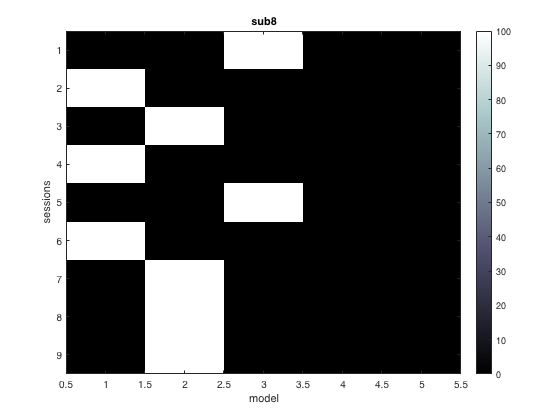

%% plotting
figure; imagesc(c_model)
title(['sub' num2str(subjID)])
xlabel('model');ylabel('sessions'); colormap(bone)
colorbar